# Lab 1 

A short lab concentrating on the meaing of 'sigma' and looking at some of the continuous and discrete analytic distributions we are likely to encounter.

## A little statistics

Converting a probability into a 'sigma'. 

This part of the lab is to figure out how, given a probability, to calculate the assoicated 'sigma' value. The sigma implicitly refers to the standard normal distribution. As we discussed in class, integrals of the standard normal distribution give probabilities.

1 - A and B

As we know Normal distributions are symmetrical, bell-shaped distributions that are useful in describing data. And Z-table is used to find the probability that a statistic is observed below, above, or between values on the standard normal distribution.

Here I try to integrating the standard normal distribution with code normcdf() with several values of sigma, and they all match the z table. The Z-table I used is cumulative, this table gives a probability between negative infinity and Z.

 probability = normcdf([0.5,1,1.5,2,2.5,3]);
 disp(probability);

    0.6915    0.8413    0.9332    0.9772    0.9938    0.9987



1 - C

Here I used several  probability values I found on the Z-table to get the associated vales of sigma 1,2,5 using code norminv().   

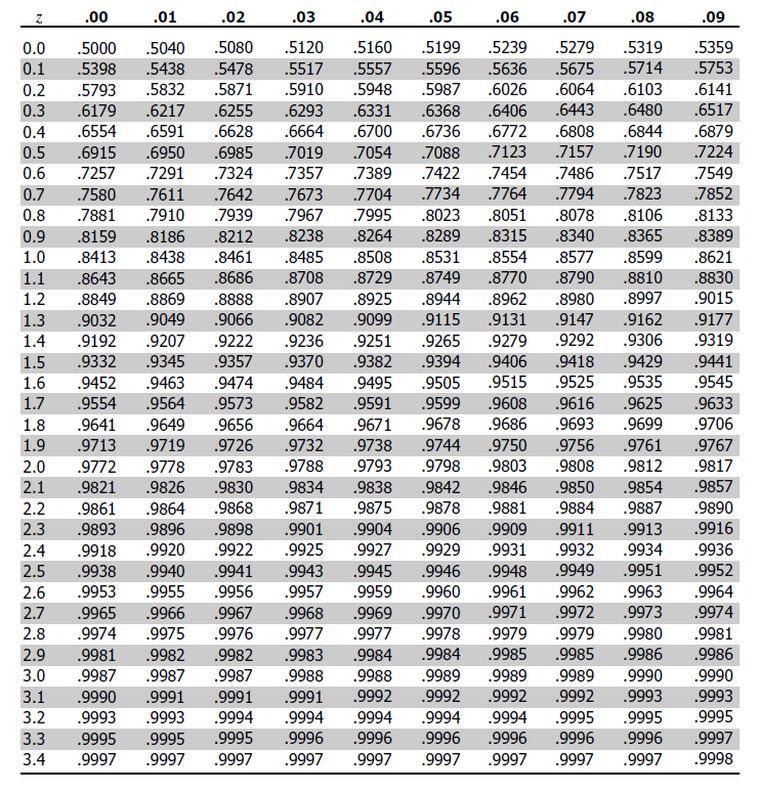

sigma = norminv([0.84134,0.97725,2.86652*10^-7]);
disp(sigma);

    1.0000    2.0000   -5.0000



1 - D

The minus sign appear because the code norminv() returns sigma, the inverse of the standard normal cumulative distribution function, evaluated at the probability values. With cumulative distribution the probability is form negative infinity to sigma. If the sigma is on the left side of mean it will be negative and probability is less than 50%. On other hand, if the sigma is on the right side of the mean it will be positive, and probability is greater than 50%. One way to make the sigma positive is to use inverse probability, since the curve of a standard normal  cumulative distribution is a bell shape and sigma is the distance away from the mean. So, the chance to find the negative sigma with given probability is the same as the chance to find the positive sigma with inverse probability.

sigma1 = norminv(1-2.86652*10^-7);
disp(sigma1);

    5.0000



2 - A

Below, I made both the analytic pdf() and a realization with ~100k samples using a built-in Gamma distributions with different shape parameters and different scale parameters. The shape parameter affects the skewness of the curve. The scale parameter stretches or squeezes a graph. 

As the shape parameter goes up the curve get skew to the left until the curve is symmetrical. When we increase the scale parameter the curve stretchers to the right. 

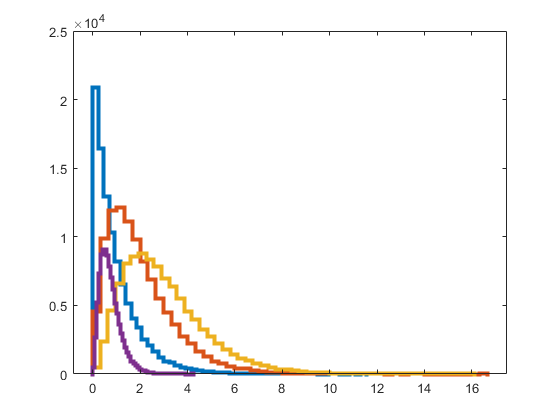

clc; close all; clear;
d1 = random('gamma', 1, 1, [1,100000]);
d2 = random('gamma', 2, 1, [1,100000]);
d3 = random('gamma', 3, 1, [1,100000]);
d4 = random('gamma', 3, 0.25, [1,100000]);

histogram(d1,50,'DisplayStyle',"stairs",'LineWidth',3)
hold on
histogram(d2,50,'DisplayStyle',"stairs",'LineWidth',3)
histogram(d3,50,'DisplayStyle',"stairs",'LineWidth',3)
histogram(d4,50,'DisplayStyle',"stairs",'LineWidth',3)

2 - B

As you can see below the plot fit the histogram for gamma graph with a shape parameter as 9 and a scale parameter 0.5.

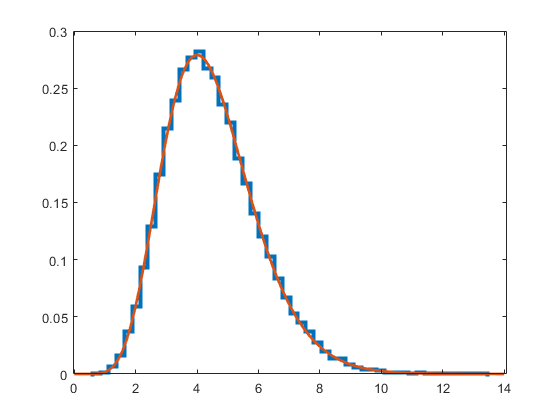

clc; close all; clear;
d = random('gamma', 9, 0.5, [1,100000]);
histogram(d,50,'DisplayStyle',"stairs",'LineWidth',3,"Normalization","pdf")
hold on
x = linspace(0,14);
pd = makedist("Gamma","a",9,"b",0.5);
plot(x,pdf(pd,x),"LineWidth",2);

3 - A, B, C, and D

The value I selected for my hypothetical measurement is 6 or above from the Gamma distribution with signal-free data. 

The statistical question I want to ask is" What is the probability and the sigma of the probability to find a value 6 or bigger on the gamma distributions with a shape parameter as 9 and a scale parameter 0.5?" 

As we know in order to find the total probability of value 6 or above, we need use integral. Integrate from 6 to positive infinity of the Gamma equation with a shape parameter as 9 and a scale parameter 0.5.


$$\int_6^{+\infty } \textrm{Gamma}\left(x,9,0\ldotp 5\right)\;\textrm{dx}$$


Below I use code cdf() to do the math and find probability for 6 or above. 

clc; close all; clear;
pd = makedist("Gamma","a",9,"b",0.5);
probability1 = cdf(pd,6,'upper');
disp("probability for fined 6 and above is " + probability1);

probability for fined 6 and above is 0.15503


3 - E

Convert my probability into an equivalent sigma using the code norminv().

sigma2 = norminv( 1-probability1);
disp("sigma for fined 6 and above is " + sigma2);

sigma for fined 6 and above is 1.0151


4

After I try various hypothetical measurement values and see the probabilities and 'sigma' change. I noticed the absolute value of sigma is the distance away from the mean of the probability curve. If the probability is less than 50% the sigma will be negative. Since the code norminv() we used is related to cumulative distribution of the probability, which is form negative infinity to sigma. If the probability is greater than 50% the sigma will be positive. I also noticed if the probability get smaller the sigma gets smaller. 

x = 1:1:10;
probability2 = cdf(pd,x,'upper');
sigma3 = norminv( probability2);
disp(x);

     1     2     3     4     5     6     7     8     9    10



disp(probability2);

    0.9998    0.9786    0.8472    0.5925    0.3328    0.1550    0.0621    0.0220    0.0071    0.0021



disp(sigma3);

    3.4945    2.0264    1.0247    0.2341   -0.4321   -1.0151   -1.5377   -2.0143   -2.4544   -2.8647



## Non-continuous distributions

1 - A and B

A binomial experiment is a statistical experiment that has many properties. One, the experiment consists of *n* repeated trials. Second, each trial can result in just two possible outcomes. We call one of these outcomes a success and the other, a failure. Third, the probability of success, denoted by *P*, is the same on every trial. Forth, the trial is independent. The code for binomial (N, P) take in two parameters. One is the number of trial 'N' and the other is the probability of success 'P'.

The code below gives us sets of binomials with different probabilities and same number of trials. As you can see form the graph when the probability is close to 50% the curve is symmetrical. When the probability gets lower than 50% the curve skew to the right. When the probability gets bigger than 50% the curve skew to the left. 

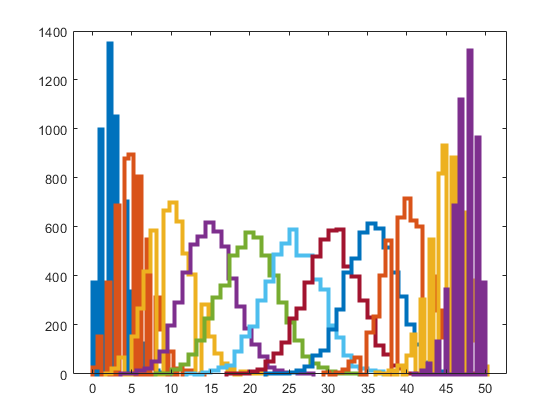

clc; close all; clear;
ntrial1 = 50;

bino0 = random('Binomial',ntrial1,0.05,[1,5000]);
bino1 = random('Binomial',ntrial1,0.1,[1,5000]);
bino2 = random('Binomial',ntrial1,0.2,[1,5000]);
bino3 = random('Binomial',ntrial1,0.3,[1,5000]);
bino4 = random('Binomial',ntrial1,0.4,[1,5000]);
bino5 = random('Binomial',ntrial1,0.5,[1,5000]);
bino6 = random('Binomial',ntrial1,0.6,[1,5000]);
bino7 = random('Binomial',ntrial1,0.7,[1,5000]);
bino8 = random('Binomial',ntrial1,0.8,[1,5000]);
bino9 = random('Binomial',ntrial1,0.9,[1,5000]);
bino10 = random('Binomial',ntrial1,0.95,[1,5000]);

histogram(bino0,25,'DisplayStyle',"stairs",'LineWidth',3)
hold on
histogram(bino1,25,'DisplayStyle',"stairs",'LineWidth',3)
histogram(bino2,25,'DisplayStyle',"stairs",'LineWidth',3)
histogram(bino3,25,'DisplayStyle',"stairs",'LineWidth',3)
histogram(bino4,25,'DisplayStyle',"stairs",'LineWidth',3)
histogram(bino5,25,'DisplayStyle',"stairs",'LineWidth',3)
histogram(bino6,25,'DisplayStyle',"stairs",'LineWidth',3)
histogram(bino7,25,'DisplayStyle',"stairs",'LineWidth',3)
histogram(bino8,25,'DisplayStyle',"stairs",'LineWidth',3)
histogram(bino9,25,'DisplayStyle',"stairs",'LineWidth',3)
histogram(bino10,25,'DisplayStyle',"stairs",'LineWidth',3)
hold off

The code below gives us sets of binomials with same probabilities and different number of trials. As you can see form the graph as the number of the trial increase the curve is get less shaper.

prob1 = 0.5

prob1 = 0.5000

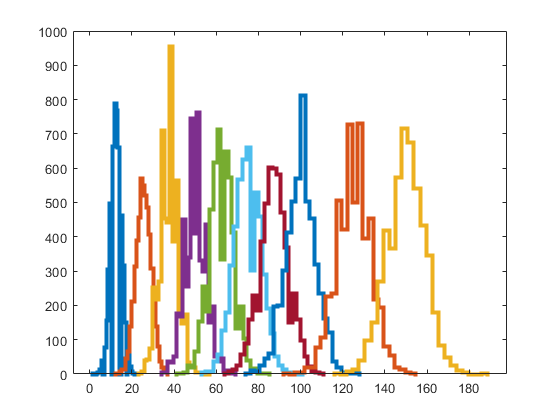

bino11 = random('binomial',25,prob1,[1,5000]);
bino12 = random('Binomial',50,prob1,[1,5000]);
bino13 = random('Binomial',75,prob1,[1,5000]);
bino14 = random('Binomial',100,prob1,[1,5000]);
bino15 = random('binomial',125,prob1,[1,5000]);
bino16 = random('Binomial',150,prob1,[1,5000]);
bino17 = random('Binomial',175,prob1,[1,5000]);
bino18 = random('Binomial',200,prob1,[1,5000]);
bino19 = random('Binomial',250,prob1,[1,5000]);
bino20 = random('Binomial',300,prob1,[1,5000]);

histogram(bino11,25,'DisplayStyle',"stairs",'LineWidth',3)
hold on
histogram(bino12,25,'DisplayStyle',"stairs",'LineWidth',3)
histogram(bino13,25,'DisplayStyle',"stairs",'LineWidth',3)
histogram(bino14,25,'DisplayStyle',"stairs",'LineWidth',3)
histogram(bino15,25,'DisplayStyle',"stairs",'LineWidth',3)
histogram(bino16,25,'DisplayStyle',"stairs",'LineWidth',3)
histogram(bino17,25,'DisplayStyle',"stairs",'LineWidth',3)
histogram(bino18,25,'DisplayStyle',"stairs",'LineWidth',3)
histogram(bino19,25,'DisplayStyle',"stairs",'LineWidth',3)
histogram(bino20,25,'DisplayStyle',"stairs",'LineWidth',3)

1 - C 

The value I selected for my hypothetical measurment is 95 or above from the bonoimial distribution with signal-free data. 

The statistical question I want to ask is" What is the probability and sigma of the probability to find 95 success rate or above for the bonoimial distribution with 100  trials and 90 percent success rate ?" 

pd1 = makedist("Binomial",100,0.9);
probability3 = cdf(pd1,95,'upper');
disp("probability for find 95 success rate and above is " + probability3);

probability for find 95 success rate and above is 0.023711


sigma4 = norminv( 1-probability3);
disp("sigma for find 95 success rate and above is " + sigma4);

sigma for find 95 success rate and above is 1.9825


1 - D and E

Because the distributions are discrete, so are the probabilities and 'sigmas'. The distribution are discrete because the trials must be natural number. For example, you can't have 4.5 trials. Since the distribution are discrete the probabilities that are assigned to each distributions must be discrete as well as the sigmas that are assigned to each probability. 

While the results are discrete, the parameters of the distributions are not. For example, the mean of a Poisson distribution can be 9.2. 

`This make sence because mean can take many numbers and averge out to get positive non-integer. For example,the mean of [1,2,3,4] is (1+2+3+4)/4 = 2.5 `